## Simulación y Control de Sistemas 

## Simulacion y Control de Sistemas con MATLAB

#### Nombre: Kevin Jimenez Rincón                       Fecha: 01/03/2024

diary diaryLab
tic


Trabajamos primeramente en el sistema dado en la guia

Modelo de FT sin tiempo muerto:

clear all
clc

s = tf('s');
Gs = 1.2/((59.7*s+1)*(22.3*s+1))

Gs =
 
          1.2
  -------------------
  1331 s^2 + 82 s + 1
 
Continuous-time transfer function.
Model Properties


Modelo de EE sin tiempo muerto:

num = cell2mat(Gs.Numerator);
den = cell2mat(Gs.Denominator);
[A,B,C,D] = tf2ss(num,den)

A =    -0.0616   -0.0008
    1.0000         0


B =      1
     0


C = 1.0e-03 *

         0    0.9014


D = 0

**5.2** Se han definido dos estructuras en el Espacio de Trabajo de Matlab, ETML, una de tipo función de

transferencia, tf (transfer function), y otra del tipo espacio de estado, ss (space state); ellas representan dos

modelos diferentes del mismo sistema, por lo que las respuestas de ambos modelos ante entrada escalón

deben ser iguales. Comprobamos con la función step que ambas son iguales

Gptf = tf(num, den)

Gptf =
 
          1.2
  -------------------
  1331 s^2 + 82 s + 1
 
Continuous-time transfer function.
Model Properties


Mpss = ss(A,B,C,D)

Mpss =
 
  A = 
               x1          x2
   x1    -0.06159  -0.0007511
   x2           1           0
 
  B = 
       u1
   x1   1
   x2   0
 
  C = 
              x1         x2
   y1          0  0.0009014
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


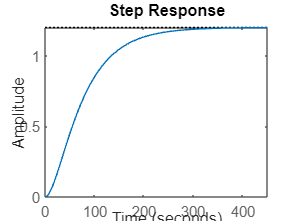


step(Gptf)

figure 
step(Mpss)

**5.2.1 **Se puede observar desde la figura que su valor final es 1.2 aunque su tiempo de estabilización alcanza a entrar desde unos pocos valores antes.

**5.2.2** Tambien podemos apreciar que su tiempo de estabilización es desde 261 segundos ya que desde ahí entra en su margen de estabilización del 2%.

**5.3** Vamos a ver las propiedades de ambos modelos sin tiempo muerto

GetG = get(Gptf)

GetG = struct with fields:
       Numerator: {[0 0 1.2000]}
     Denominator: {[1.3313e+03 82 1]}
        Variable: 's'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 0
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: 0
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]


GetEE = get(Mpss)

GetEE = struct with fields:
                A: [2×2 double]
                B: [2×1 double]
                C: [0 9.0137e-04]
                D: 0
                E: []
           Scaled: 0
        StateName: {2×1 cell}
        StatePath: {2×1 cell}
        StateUnit: {2×1 cell}
    InternalDelay: [0×1 double]
       InputDelay: 0
      OutputDelay: 0
        InputName: {''}
        InputUnit: {''}
       InputGroup: [1×1 struct]
       OutputName: {''}
       OutputUnit: {''}
      OutputGroup: [1×1 struct]
            Notes: [0×1 string]
         UserData: []
             Name: ''
               Ts: 0
         TimeUnit: 'seconds'
     SamplingGrid: [1×1 struct]


**5.3.1** Seguidamente vamos a agregar el tiempo muerto a nuestros modelos


Gptfm = Gptf, Mpssm = Mpss

Gptfm =
 
          1.2
  -------------------
  1331 s^2 + 82 s + 1
 
Continuous-time transfer function.
Model Properties

Mpssm =
 
  A = 
               x1          x2
   x1    -0.06159  -0.0007511
   x2           1           0
 
  B = 
       u1
   x1   1
   x2   0
 
  C = 
              x1         x2
   y1          0  0.0009014
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


Gptfm.InputDelay=39.2

Gptfm =
 
                         1.2
  exp(-39.2*s) * -------------------
                 1331 s^2 + 82 s + 1
 
Continuous-time transfer function.
Model Properties


Mpssm.InputDelay=39.2

Mpssm =
 
  A = 
               x1          x2
   x1    -0.06159  -0.0007511
   x2           1           0
 
  B = 
       u1
   x1   1
   x2   0
 
  C = 
              x1         x2
   y1          0  0.0009014
 
  D = 
       u1
   y1   0
 
  Input delays (seconds): 39.2 
 
Continuous-time state-space model.


Vamos a ver ahora las propiedades de nuestros modelos con tiempo muerto

GetGtm = get(Gptfm)

GetGtm = struct with fields:
       Numerator: {[0 0 1.2000]}
     Denominator: {[1.3313e+03 82 1]}
        Variable: 's'
         IODelay: 0
      InputDelay: 39.2000
     OutputDelay: 0
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: 0
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]


GetEEtm = get(Mpssm)

GetEEtm = struct with fields:
                A: [2×2 double]
                B: [2×1 double]
                C: [0 9.0137e-04]
                D: 0
                E: []
           Scaled: 0
        StateName: {2×1 cell}
        StatePath: {2×1 cell}
        StateUnit: {2×1 cell}
    InternalDelay: [0×1 double]
       InputDelay: 39.2000
      OutputDelay: 0
        InputName: {''}
        InputUnit: {''}
       InputGroup: [1×1 struct]
       OutputName: {''}
       OutputUnit: {''}
      OutputGroup: [1×1 struct]
            Notes: [0×1 string]
         UserData: []
             Name: ''
               Ts: 0
         TimeUnit: 'seconds'
     SamplingGrid: [1×1 struct]


**5.3.2 **Vamos a graficar las respuestas a nuestros modelos pero ahora con tiempo muerto

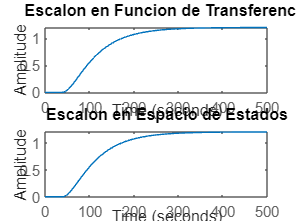

figure
subplot(2,1,1);
step(Gptfm)
title('Escalon en Funcion de Transferencia')
subplot(2,1,2)
step(Mpssm)
title('Escalon en Espacio de Estados')

Ahora podemos observar que ambos modelos tienen el tiempo muerto por lo cual si bien su valor final de estabilización es el mismo a los que no poseian el tiempo muerto pero por el tiempo muerto agregado su tiempo de estabilizacion si asciende a 301 segundos

**5.3.3**

NUM = get(Gptfm,"Numerator");
DEN = get(Gptfm, "Denominator");
TM = get(Gptfm, "InputDelay");

**5.4** Ahora, vamos a crear estructuras a partir de una estructura existente 

 systf = tf(Mpss) % se define un sistema como TF a partir de una representación de EE

systf =
 
           0.0009014
  ---------------------------
  s^2 + 0.06159 s + 0.0007511
 
Continuous-time transfer function.
Model Properties


 sysss = ss(Gptf) % se define un sistema en el EE a partir de una TF

sysss =
 
  A = 
             x1        x2
   x1  -0.06159  -0.02404
   x2   0.03125         0
 
  B = 
          u1
   x1  0.125
   x2      0
 
  C = 
           x1      x2
   y1       0  0.2308
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


 syszpk = zpk(Gptf) % se define un sistema con factores de ceros, polos y una ganancia a partir de una tf

syszpk =
 
        0.00090137
  -----------------------
  (s+0.04484) (s+0.01675)
 
Continuous-time zero/pole/gain model.
Model Properties


¿Existen otras opciones de conversión de estructuras?

    R/ Si, con la funcion struct podríamos tambien crear estructuras

¿systf y sysss son iguales a las expresiones Gptf y Mpss que usted manejó en 5.2?

 figure
 step(systf)

 figure
 step(sysss)

Comentario: Podemos observar que si bien son diferentes expresiones las respuestas al escalon son exactamente iguales por lo que seguimos trabajando con los mismos modelos, la razon de la diferencia de expresiones seguramente se deba a el como MATLAB trabaja las ecuaciones.

**5.5 **Vamos a hallar la respuesta al escalon de Gptfm

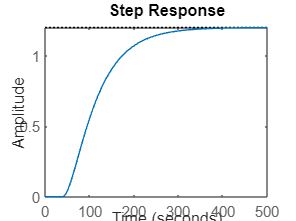

 step(Gptfm)

**5.5.2 **Vamos a crear una FT según la descrita en la guía razón por la cual debemos hallar los polos, ver el tiempo muerto del sistema y ya creariamos la funcion que se vería así

Gctf = 0.3*tf(den,[39.2,1]);

**5.5.3 **Vamos a crear una nueva variable de red abierta llamada Gatfm que sera = Gct*Gptfm

Gatfm = minreal(Gctf*Gptfm)

Gatfm =
 
                  0.009184
  exp(-39.2*s) * -----------
                 s + 0.02551
 
Continuous-time transfer function.
Model Properties


**5.5.4 **

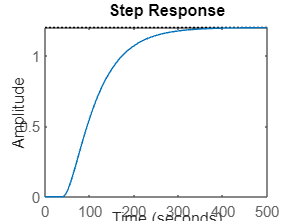

step(Gptfm)

Podemos observar que al final van a ser las mismas ya que si trabjamos sin Gc sería lo mismo que aplicar el escalon normalmente

**5.5.5 **Si P(s)=0 y E(s) es el escalón unitario, en una nueva ventana de figura halle yr(t).

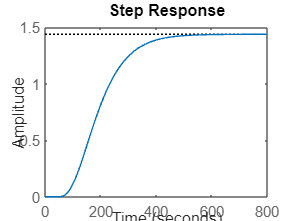

step(Gs*Gptfm)

¿Qué diferencias y similitudes observa de esta respuesta con respecto a la hallada en 4.5.Compare

tiempos de estabilización, sobre nivel porcentual, valores de estado estable.

Diferencias y similitudes: La amplitud de la figura de 5.5 es menor que la amplitud de la figura 5.5.5 mientras que el tiempo que tardan en estabilizarse es mayor en la figura del punto 5.5.5.

Sus tiempos muertos son iguales por los que no se podría decir que esto fue influyente en las diferencias entre estos dos

¿Considera usted que esta última respuesta es mejor, igual o peor que la inicial?

¿Por qué?

    R/ es peor, si bien son sutiles diferencias siempre va a ser preferible el sistema que se estabilice más rápido 

**5.6. **

**5.6.1. **Vamos a pasar Gatfm y Gptfm a espacio de estados

Massm = ss(Gatfm) 

Massm =
 
  A = 
             x1
   x1  -0.02551
 
  B = 
          u1
   x1  0.125
 
  C = 
            x1
   y1  0.07347
 
  D = 
       u1
   y1   0
 
  Input delays (seconds): 39.2 
 
Continuous-time state-space model.
Model Properties


Mpssm = ss(Gptfm)

Mpssm =
 
  A = 
             x1        x2
   x1  -0.06159  -0.02404
   x2   0.03125         0
 
  B = 
          u1
   x1  0.125
   x2      0
 
  C = 
           x1      x2
   y1       0  0.2308
 
  D = 
       u1
   y1   0
 
  Input delays (seconds): 39.2 
 
Continuous-time state-space model.


**5.6.2 **

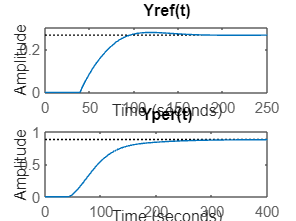

subplot(2,1,1);
step((Gatfm)/(1 + Gatfm))
title('Yref(t)')


subplot(2,1,2);
step((Gptfm)/(1 + Gatfm))
title('Yper(t)')

Con respecto a la señal P(s), ¿Cuál de las respuestas 5.5.4 y 5.6.2 es mejor?

¿Por qué?    

    R/ La 5.6.2 ya que su tiempo de estabilización es menor aunque su ganancia es corta, pero vamos a preferir un modelo que tienda a la estabilidad más rápido

¿Se puede decir que la realimentación ha influído de manera evidente en la respuesta ante la

misma entrada?

¿Por qué?

    R/ si claro, ya que se demuestra la diferencia en el sobrenivel que se creó

Con respecto a la señal R(s), ¿Cuál de las respuestas 5.5.5 y 5.6.2 es mejor?

¿Por qué?

    R/ la 5.5.5 ya que la 5.6.2 demora mucho en 'tiempo muerto' y además tiene un pequeño sobreimpuslo

**5.6.3** Halle la respuesta del sistema de la figura 7 cuando el controlador tiene ganancia de 0.2 y compárela

con la hallada en 5.6.2. ¿Cuál respuesta es mejor?


Gctf_2 = 0.2*tf(den,[39.2,1]);
Gatfm_2 = minreal(Gctf_2*Gptfm)

Gatfm_2 =
 
                  0.006122
  exp(-39.2*s) * -----------
                 s + 0.02551
 
Continuous-time transfer function.
Model Properties


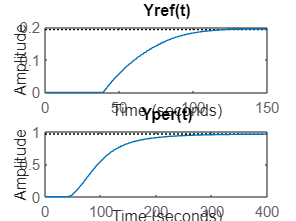

figure
subplot(2,1,1);
step((Gatfm_2)/(1 + Gatfm_2))
title('Yref(t)')


subplot(2,1,2);
step((Gptfm)/(1 + Gatfm_2))
title('Yper(t)')

con la hallada en 5.6.2. ¿Cuál respuesta es mejor?

R/ En cuanto a Yper esta última ya que tiene mejor ganancia para un sistema que tiende a estabilizarse al mismo tiempo y para Yref la consideración sería si se prefiere en su sistema un sobrenivel o mayor tiempo muerto

**Conclusiones:**

-Si bien el modelo de estados y la función de transferencia tienen diferentes expresiones matematicas la respuesta escalón es similar en ambas

-La respuesta al escalón con tiempo muerto tiene un tiempo de estabilización mayor en comparación con los modelos sin tiempo muerto.

-La diferencia de una ganancia u otra afecta la respuesta del sistema. Se pueden observar diferencias en los tiempos de estabilización debido a estas.

-La realimentación afecta la respuesta del sistema. Se observa su influencia en los sobreniveles y tiempos de estabilización

toc
diary
